# Update Friend Information in Social Neighborhood

This example shows how to create, update, and delete information in a social neighborhood, which is represented by a Neo4j® database, using the MATLAB® interface to Neo4j.

For details about the MATLAB interface to Neo4j, see [Working with MATLAB Interface to Neo4j](docid:database_ug.bveys16-1).

Assume that you have graph data stored in a Neo4j database that represents the social neighborhood. This database has seven nodes and eight relationships. Each node has only one unique property key `name` with a value ranging from `User1` through `User7`. Each relationship has the type `knows`.

The local machine hosts the Neo4j database with the port number `7474`, user name `neo4j`, and password `matlab`. This figure provides a visual representation of the data in the database.

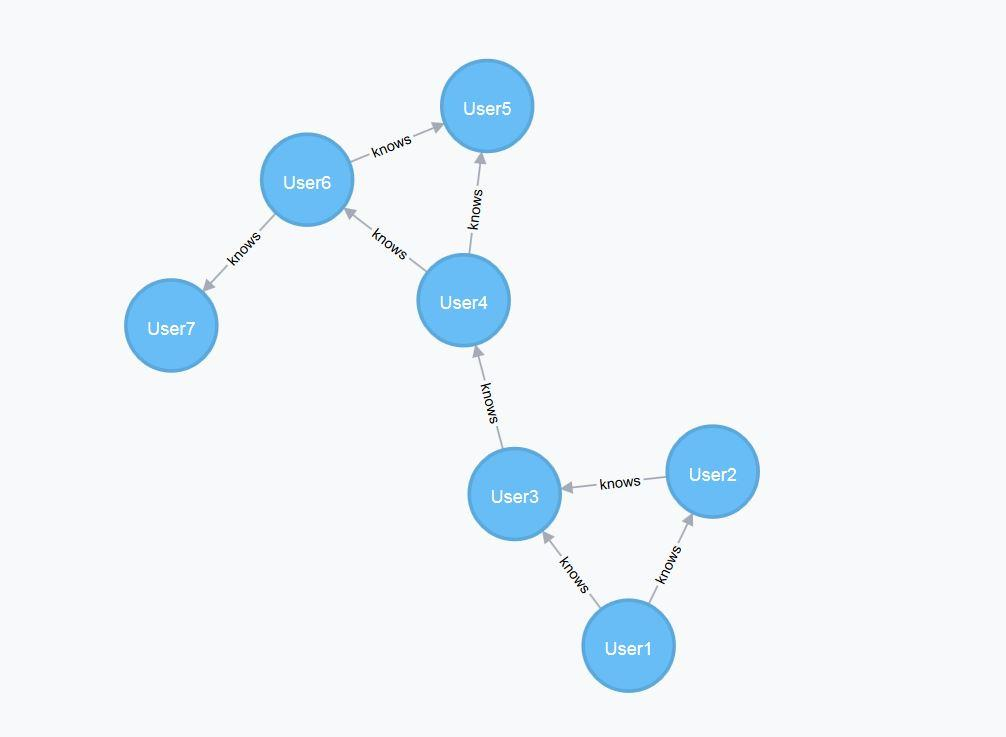

## Connect to Neo4j Database

Create a Neo4j connection object `neo4jconn` using the URL `http://localhost:7474/db/data`, user name `neo4j`, and password `matlab`.

url = 'http://localhost:7474/db/data';
username = 'neo4j';
password = 'matlab';

neo4jconn = neo4j(url,username,password);

Check the `Message` property of the Neo4j connection object `neo4jconn`. The blank `Message` property indicates a successful connection.

neo4jconn.Message

## Add Two Friends to Social Neighborhood

Create two nodes in the database using the Neo4j database connection. Use the `'Labels'` name-value pair argument to specify the label `Person` for each node.

label = 'Person';
user8 = createNode(neo4jconn,'Labels',label);
user9 = createNode(neo4jconn,'Labels',label);

Search for the node with the label `Person` and the property key `name` set to the value `User7` by using the Neo4j database connection.

nlabel = 'Person';
user7 = searchNode(neo4jconn,nlabel,'PropertyKey','name', ...
    'PropertyValue','User7');

Create two relationships using the Neo4j database connection. Specify the relationship types as `works with` and `studies with`. The two relationships are:

- `User8` works with `User7`

- `User8` studies with `User9`

`relationinfo` is a table that contains the relationship and node information.

startnode = [user8,user8];
endnode = [user7,user9];
relationtype = {'works with','studies with'};
relationinfo = createRelation(neo4jconn,startnode,endnode,relationtype);

## Update Node Information for Added Friend

Update the properties of the node `User8`. Create a table with one row that contains the name and job title for this person. `nodeinfo` is a `Neo4jNode` object.

properties = table("User8","Analyst",'VariableNames',{'Name','Title'});
nodeinfo = setNodeProperty(neo4jconn,user8,properties);

Add the node label `Student` to `User9`.

labels = 'Student';
nodeinfo = addNodeLabel(neo4jconn,user9,labels);

## Update Relationship Information for Added Friends

Create a table that defines the relationship properties. Here, `User8` works with `User7` in the workplace, and `User8` studies with `User9` in the library. Also, `User8` started working with `User7` on January 2, 2017, and `User8` started studying with `User9` on March 6, 2017.

properties = table(["Workplace";"Library"],["01/02/2017";"03/06/2017"], ...
    'VariableNames',{'Location','Date'});

Update both relationships with these properties. `relationinfo` is a table that contains the updated relationships.

relations = relationinfo.RelationObject;
relationinfo = setRelationProperty(neo4jconn,relations,properties);

## Delete Relationship for Added Friend

Delete the relationship that connects `User8` to `User7`.

relation = relations(1);
deleteRelation(neo4jconn,relation)

## Delete Friends

Delete the added nodes and any associated relationships.

nodes = [user8,user9];
deleteNode(neo4jconn,nodes,'DeleteRelations',true)

## Close Database Connection

close(neo4jconn)

*Copyright 2018 The MathWorks, Inc.*